Example

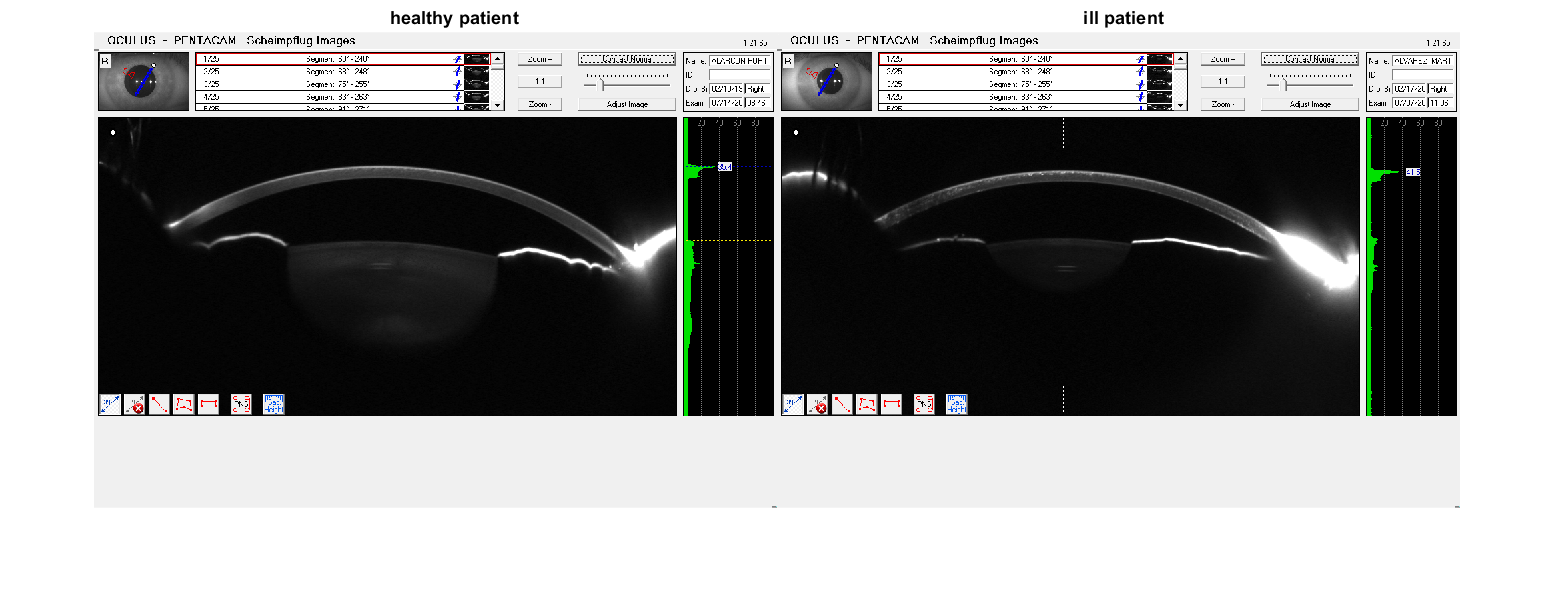

healthy_patient=imread('D:\OneDrive - URV\Universidad\QuintoAny\Computer Vision\lab\practica\Imatges cistinosis\PAC\PAC1\PAC1_20160714_084632_PENTACAM_R_01.BMP');
ill_patient=imread('D:\OneDrive - URV\Universidad\QuintoAny\Computer Vision\lab\practica\Imatges cistinosis\PAC\PAC4\PAC4_20160707_110642_PENTACAM_R_01.BMP');


%figure, imshow(healthy_patient); 
imshowpair(healthy_patient, ill_patient, "montage");
title('healthy patient                                                                                                               ill patient');

## 1. Localización de la cornea

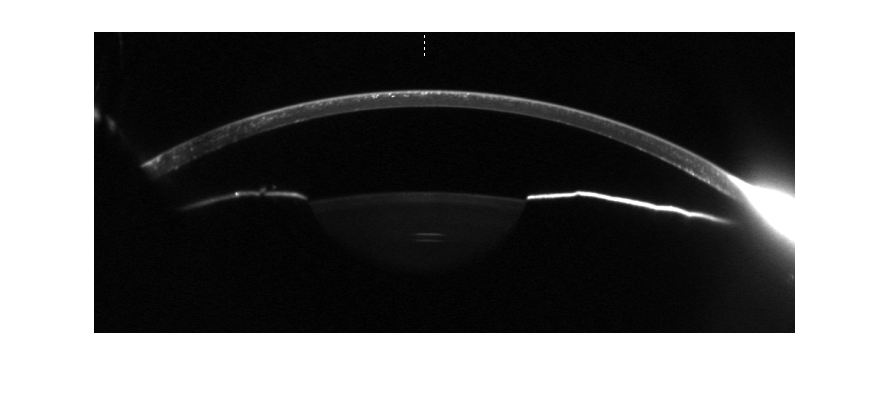

patient_crop = imcrop(ill_patient, [100 150 700 300]); imshow(patient_crop);

patient_grey = rgb2gray(patient_crop); imshow(patient_grey);

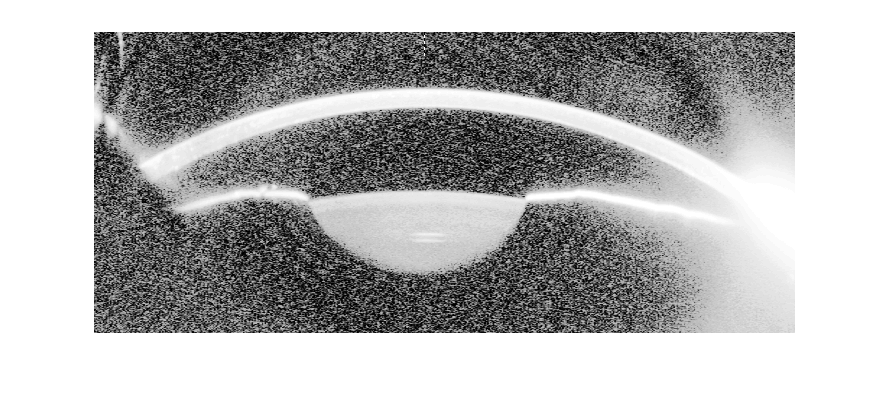

patient_ecual = histeq(patient_grey); imshow(patient_ecual);

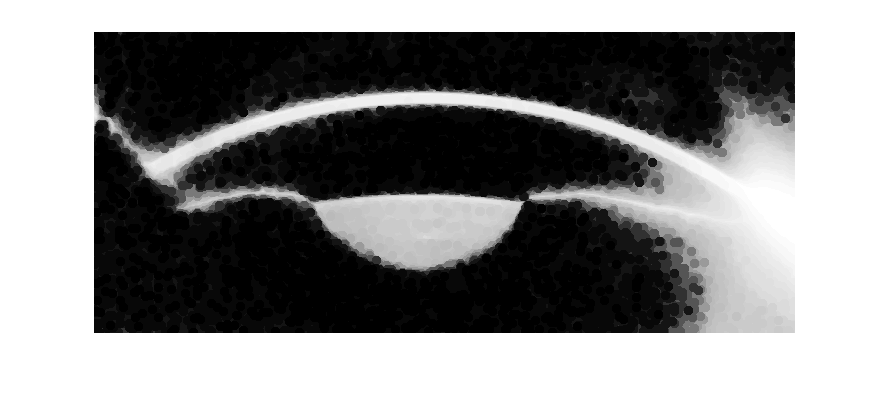

patient_erosion = imerode(patient_ecual, strel('disk', 5)); imshow(patient_erosion);

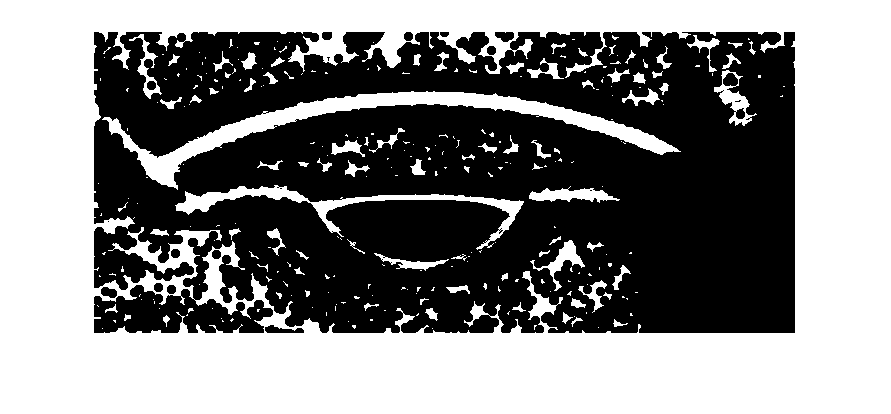

patient_erosion_bin = imbinarize(patient_erosion, "adaptive", "sensitivity", 0.01); imshow(patient_erosion_bin);

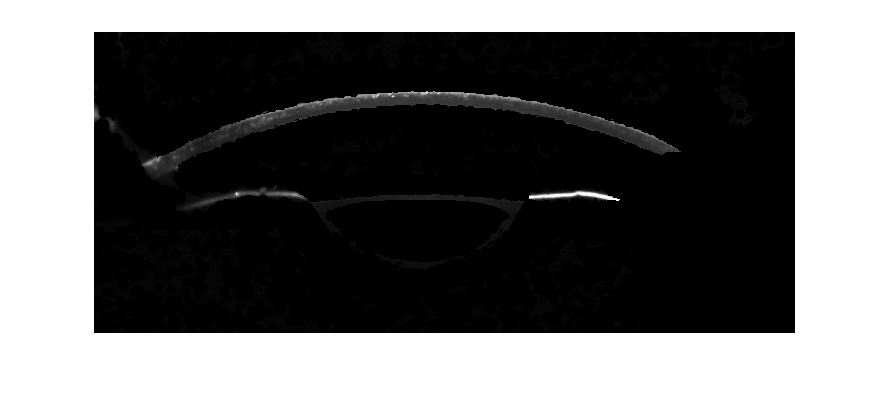

patient_masked = patient_grey .* uint8(patient_erosion_bin); imshow(patient_masked);

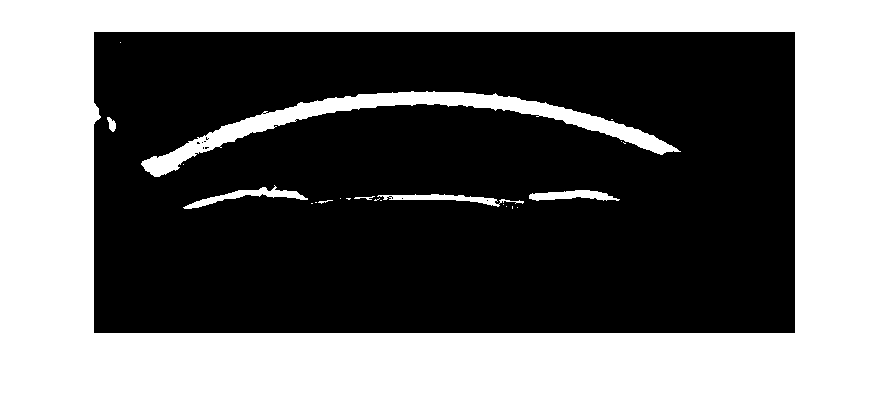

patient_bin = imbinarize(patient_masked, 0.1); imshow(patient_bin);

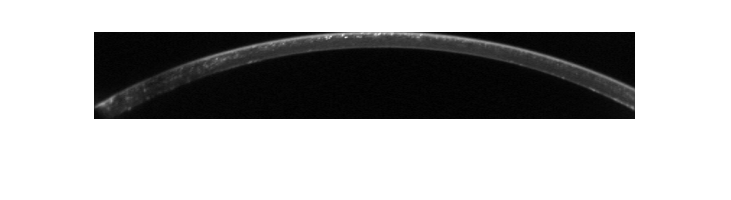

boundingboxes = regionprops(patient_bin, "area", "BoundingBox");   % Trobem els bounding boxes dels objectes de la imatge

[max_area, max_index] = max([boundingboxes.Area]);
patient_cornea = imcrop(patient_grey, boundingboxes(max_index).BoundingBox); imshow(patient_cornea);  % Obté la còrnea delimitada pel boundingbox trobat

## 2. Aplanamiento de la cornea

patient_cornea = imcrop(patient_grey, boundingboxes(max_index).BoundingBox); imshow(patient_cornea);

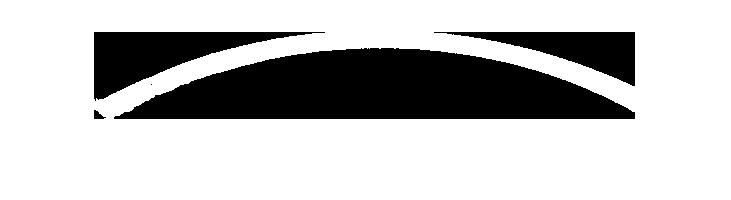

patient_cornea_bin = imbinarize(patient_cornea, 0.08); imshow(patient_cornea_bin); 

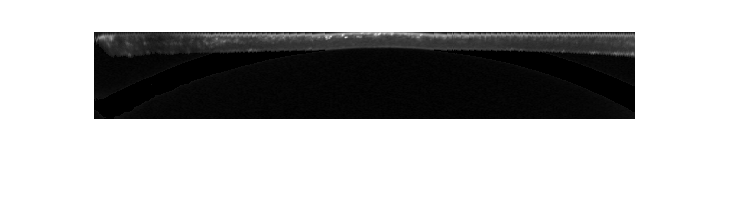

% Binary image: 0->Negro, 1->Blanco

for y = 1 : size(patient_cornea, 2)  
    x_ini = 1;  % x es la posicio on es recolocaran els pixels de la cornea corva
    for x = 1 : size(patient_cornea, 1)
        if patient_cornea_bin(x, y) == 1 
            patient_cornea(x_ini, y) = patient_cornea(x,y);
            if (x_ini  ~= x)  % Cas especial per quan la cornea comença a la primera linia
                patient_cornea(x, y) = 0; 
            end
            x_ini = x_ini + 1;
        end
    end
end
imshow(patient_cornea);

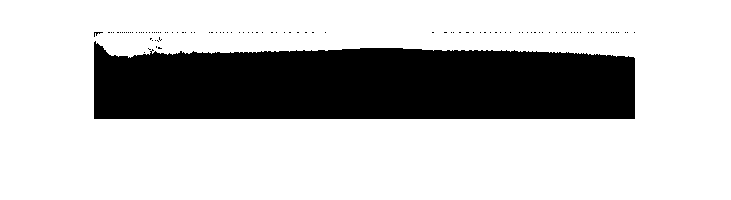

patient_cornea_bin = imbinarize(patient_cornea, 0.1); imshow(patient_cornea_bin)

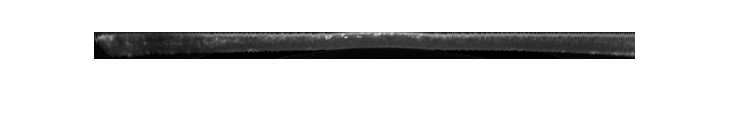

boundingboxes = regionprops(patient_cornea_bin, "area", "BoundingBox");   % Trobem els bounding boxes dels objectes de la imatge

[max_area, max_index] = max([boundingboxes.Area]);
patient_cornea_only = imcrop(patient_cornea, boundingboxes(max_index).BoundingBox); imshow(patient_cornea_only);  % Obté la còrnea delimitada pel boundingbox trobat

## 3. **Segmentación en secciones y conteo de cristales y nivel de gris**

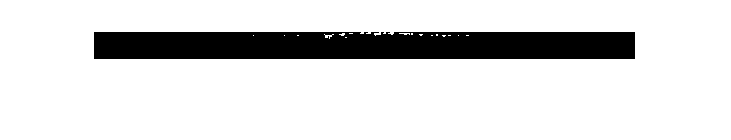

[max_y, max_x] = size(patient_cornea_only);

min_y_superficie = 0;
min_y_profundo = max_y * 300/550;
height_superficie = min_y_profundo;
height_profundo = max_y - min_y_profundo;

min_x_izq = 0;
min_x_centro = max_x * 4/12;
min_x_der = max_x * 8/12;
width_izq = min_x_centro;
width_centro = min_x_der - min_x_centro;
width_der = max_x - min_x_der;


zones = [min_x_izq, min_y_superficie, width_izq, height_superficie;... %PS
         min_x_centro, min_y_superficie, width_centro, height_superficie;... %CS   
         min_x_der, min_y_superficie, width_der, height_superficie;... %PS
         min_x_izq, min_y_profundo, width_izq, height_profundo;... %PP
         min_x_centro, min_y_profundo, width_centro, height_profundo;... %CP  
         min_x_der, min_y_profundo, width_der, height_profundo; %PP
         ];

binarized_ima = imbinarize(patient_cornea_only, 0.6);  % Threshold per binaritzar i detectar cristalls HC
imshow(binarized_ima)


for i=1 : length(zones)
    segmento = imcrop(binarized_ima, zones(i,:)); % Recortamos el segmento
    [num_pixels, ~] = imhist(segmento); % histograma de cada zona. Num pixels es el recuento de pixeles negros y blancos. 
    n_cristales(i) = num_pixels(2); % nos quedamos con el nº de blancos
    cristal_only_segment = imcrop(patient_cornea_only, zones(i,:)) .* uint8(segmento); 
    [num_pixels_gris, valores_gris] = imhist(cristal_only_segment);
    suma_valores_grises = 0;
    for j = 1 : length(valores_gris)
        suma_valores_grises = suma_valores_grises + valores_gris(j) * num_pixels_gris(j);
    end
    if n_cristales(i) ~= 0
        suma_valores_grises_normalizado(i) = suma_valores_grises / n_cristales(i);
    else
        suma_valores_grises_normalizado(i) = 0;
    end
end

n_cristales(1) = n_cristales(1) + n_cristales(3);
n_cristales(4) = n_cristales(4) + n_cristales(6);

plot("25/05/2021", n_cristales(1), "25/05/2021", n_cristales(2), "25/05/2021", n_cristales(4), "25/05/2021", n_cristales(5))

Error using plot
Not enough input arguments.